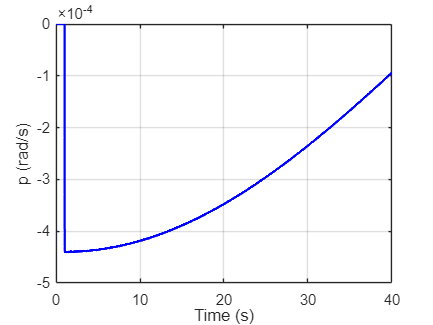

clear
clc


% 0 Controller value

Kp_a = 11.5;

% 1 Run model
open('Roll_Rate_Damper.slx')
out = sim('Roll_Rate_Damper.slx');

% 2 Extract time and signal data
t = out.p.Time;      % Time vector
p = out.p.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% Plot for verification
figure;
plot(t, p, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('p (rad/s)');
grid on;


% Compute step response characteristics
info = stepinfo(p, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 0.0013
    TransientTime: 39.5280
     SettlingTime: 39.8681
      SettlingMin: -4.4034e-04
      SettlingMax: -9.4414e-05
        Overshoot: 365.7057
       Undershoot: 0
             Peak: 4.4034e-04
         PeakTime: 1.0700

